clear; close all;


# Geometric Planning

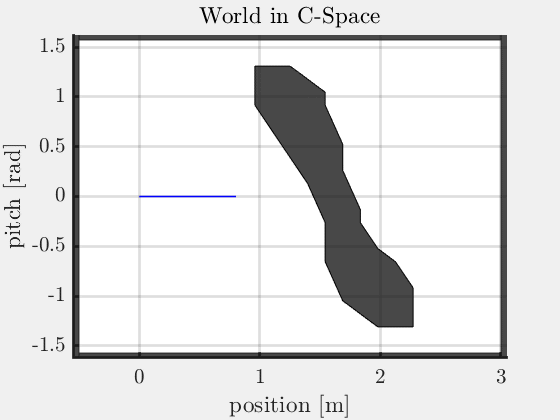

### Setting up the C-Space World

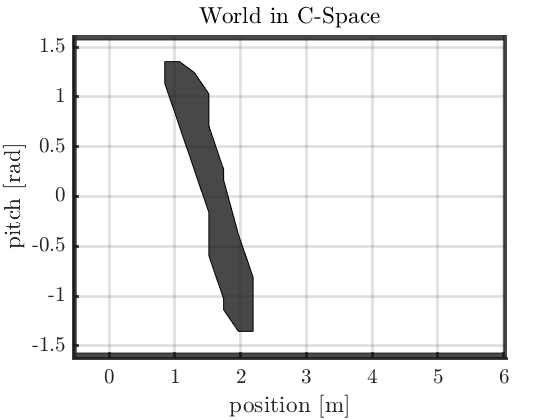

% C-Space boundaries
pitch_max    = deg2rad(90);
pitch_min    = deg2rad(-90);
position_max = 6;
position_min = -0.5;
% Setup the C-Space world using the pre-programmed class
% "CGeometricConfigWorld"
cspace = CGeometricConfigWorld(pitch_max, pitch_min, position_max, position_min);
% Load our obstacle polygon
load('1_Data/obstacle.mat');
% Add the obstacle to our world
cspace.addObstacle(obstacle_polygon);
% Let's draw the world
figure;
cspace.draw();

### Setting up the Planning

% Initial configuration
y_I = [0; 0];
% Function for computing distance between two configurations (using the
% pre-programmed function "configuration_distance")
distance_func = @configuration_distance;

### Let's explore unknown worlds

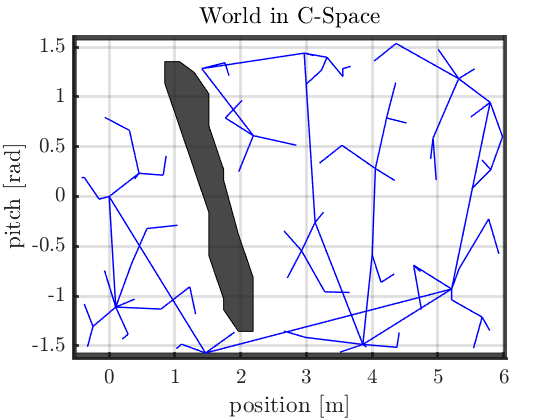

% Set a fixed RNG-seed for reproducible results
rng(1);
% Set the number of RRT-iterations
K = 100;
% Explore using the pre-programmed function "geometric_exploration"
tree = geometric_exploration(y_I, cspace, distance_func, K);
figure;
cspace.draw();
tree.draw('blue');

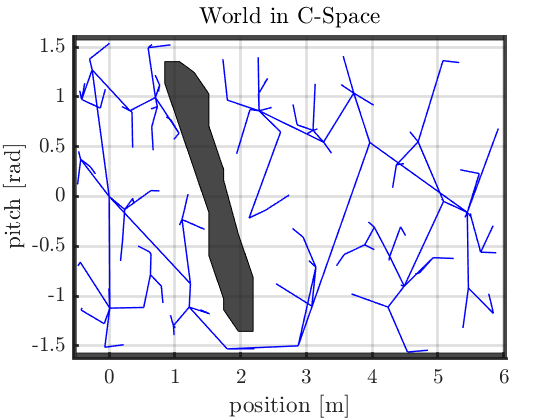

% Let's repeat with a larger number of RRT-iterations
K    = 200;
tree = geometric_exploration(y_I, cspace, distance_func, K);
figure;
cspace.draw();
tree.draw('blue');

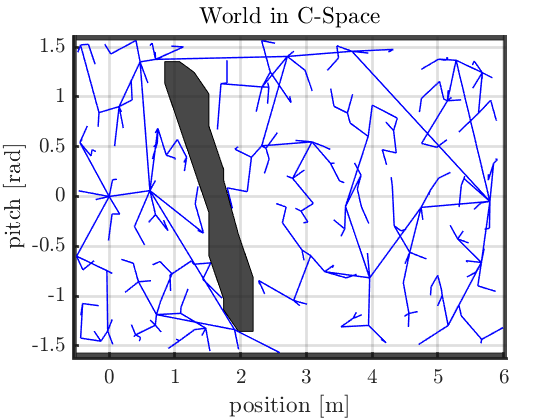

% And again
K = 400;
tree = geometric_exploration(y_I, cspace, distance_func, K);
figure;
cspace.draw();
tree.draw('blue');

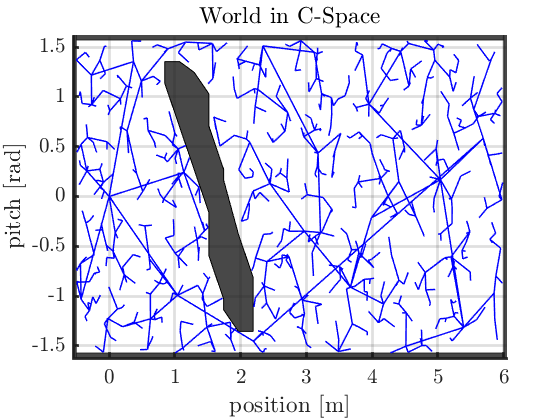

% And again
K = 800;
tree = geometric_exploration(y_I, cspace, distance_func, K);
figure;
cspace.draw();
tree.draw('blue');

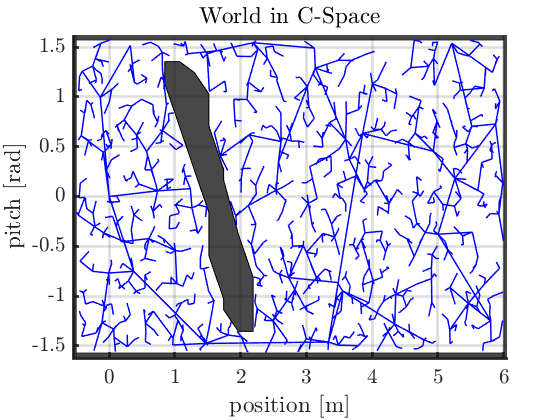

% And again
K = 1200;
tree = geometric_exploration(y_I, cspace, distance_func, K);
figure;
cspace.draw();
tree.draw('blue');

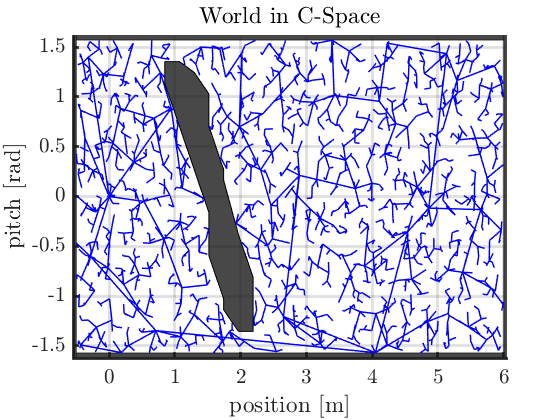

% And again
K = 2000;
[tree, nodelist] = geometric_exploration(y_I, cspace, distance_func, K);
figure;
cspace.draw();
tree.draw('blue');

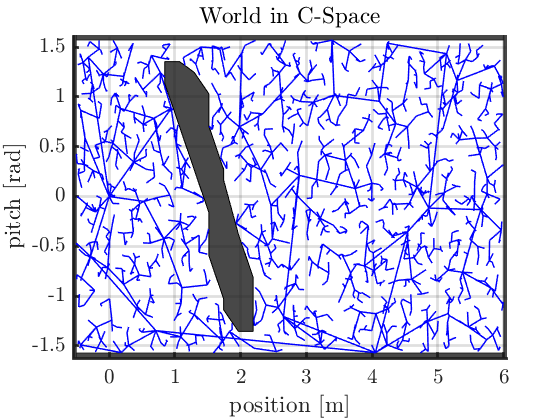

% Let's watch the tree grow
geometric_rrt_animation(cspace, nodelist);

### Let's plan

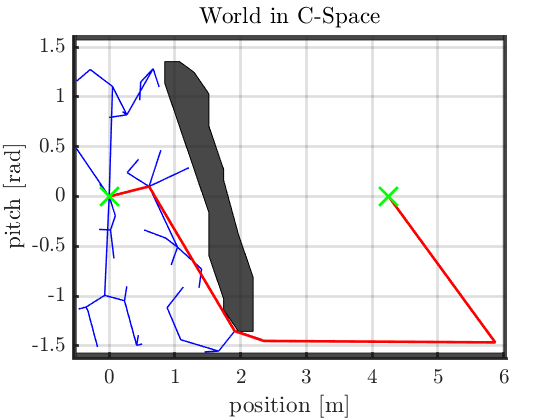

% Define the goal configuration
y_G = [0; 4.25];
% Define maximum number of RRT-iterations
K = 500;
% Set goal-check-probability
goal_check_probability = 0.99;
% Let's go
[success, tree, path] = geometric_planning(y_I, y_G, cspace, distance_func, K, goal_check_probability);
% If planning succeeded, draw the results
if(success == true)
    figure;
    cspace.draw();
    tree.draw('blue');
    plot(path(2,:), path(1,:), '-', 'LineWidth', 2, 'Color', 'red');
    plotConfiguration(y_I, 'green');
    plotConfiguration(y_G, 'green');
end

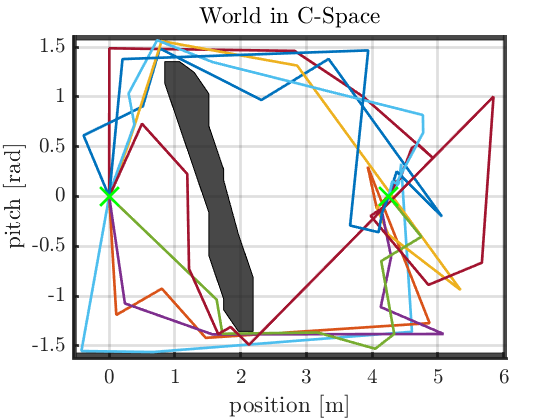


% Let's create a couple of plans and compare the results
figure;
cspace.draw();
for j = 1:10
    [success, tree, path] = geometric_planning(y_I, y_G, cspace, distance_func, K, goal_check_probability);
    if(success == true)
        plot(path(2,:), path(1,:), '-', 'LineWidth', 2);
    end
end
plotConfiguration(y_I, 'green');
plotConfiguration(y_G, 'green');

#### Creating a Trajectories over Time

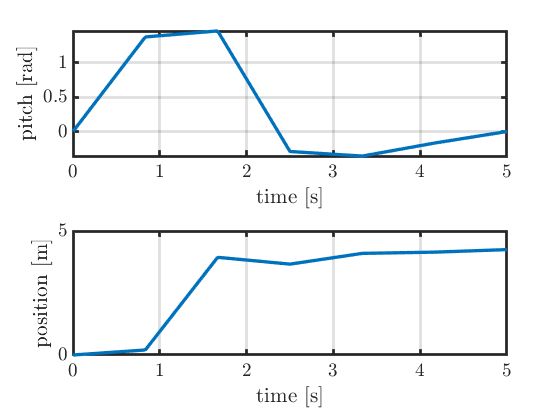

% The path only exists in C-Space
% To create a trajectory (a function over time) we ...
% choose a sampling period of 0.02 seconds,
T      = 0.02;
% choose a trajectory length of 5 seconds,
T_traj = 5;
% create a time vector for the trajectories
t_traj = (0:T:T_traj)';
% create a time vector of our original path
nbrOfPathSamples = size(path, 2);
t_path           = (0:nbrOfPathSamples-1)*T_traj/(nbrOfPathSamples-1);
% create the pitch and position trajectory by linear interpolation
pitch_traj    = interp1(t_path, path(1,:), t_traj);
position_traj = interp1(t_path, path(2,:), t_traj);
% Let's plot the planned trajectories over time
figure;
plotTrajectoriesOverTime(t_traj, pitch_traj, position_traj);

### Let's experiment

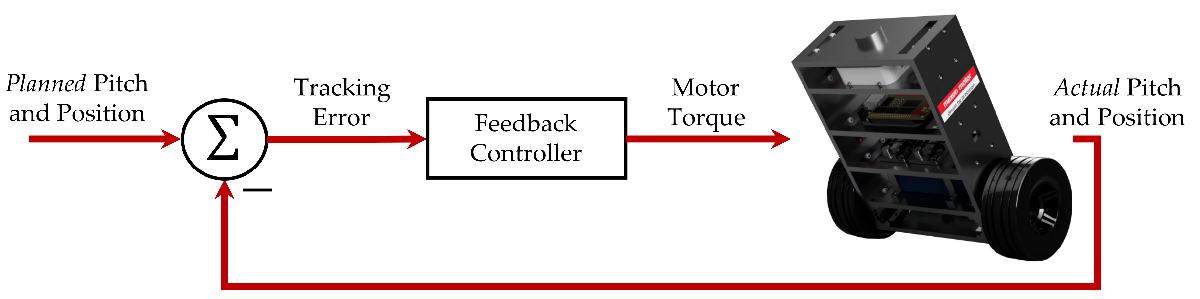

% Simulate TWIPR using pre-programmed function "sim_TWIPR_FeedbackControl"
[real_pitch, real_position] = sim_TWIPR_FeedbackControl(pitch_traj, position_traj);

% Plot Results
plotTrajectoriesOverTime(t_traj, real_pitch, real_position);
legend('planned', 'real','Location', 'nw');

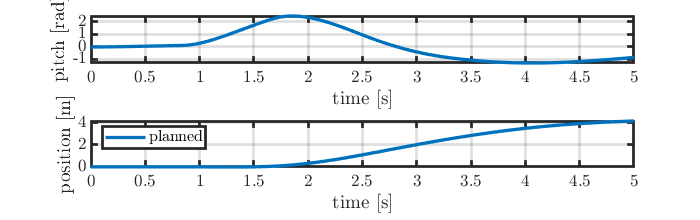

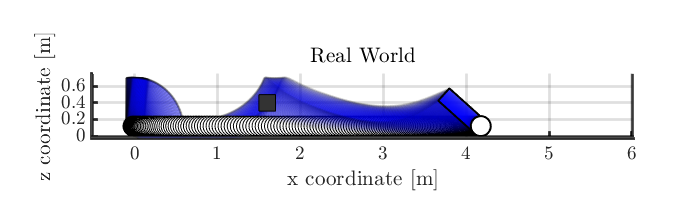


% Let's look at the resulting movement in the real world
load('1_Data\real_world.mat');
animate_movement_real_world(real_world, real_pitch, real_position);